# Opgave 1 E15

clear

a = 1; b = 3; c = 2; % m
u = 30*pi/180; % rad
v = 60*pi/180; % rad
w = 90*pi/180; % rad

U = [cos(u), -sin(u), 0; sin(u), cos(u), 0; 0, 0, 1]
V = [cos(v), 0, sin(v); 0, 1, 0;-sin(v), 0, cos(v)]
W = [cos(w), 0, -sin(w); 0, 1, 0; sin(w), 0, cos(w)]

A = [0, 0, a]'
B = [0, 0, b]'
C = [0, 0, -c]'

P = U*(V*(W*C+B)+A)


clear
syms u v w x y z a b c
f = [cos(u)*(b*sin(v)-c*sin(v-w)) - x

        sin(u)*(b*sin(v)-c*sin(v-w)) - y

        a + b*cos(v)-c*cos(v-w) - z];

jacobian(f, [u,v,w])


clear

a = 1; b = 3; c = 2; % m
x = 1.1; y = 2.8; z = 0.6; % m
u0 = 45*pi/180; % rad
v0 = 30*pi/180; % rad
w0 = 55*pi/180; % rad
es = 0.0001; maxit = 20; % Ønsket nøjagtighed (%) og maks iterationer
X = [u0; v0; w0];
iter = 0;
while 1
    u = X(1); v = X(2); w = X(3);

    f = [cos(u)*(b*sin(v)-c*sin(v-w)) - x

        sin(u)*(b*sin(v)-c*sin(v-w)) - y

        a + b*cos(v)-c*cos(v-w) - z];

    J = [-sin(u)*(b*sin(v)-c*sin(v-w)) cos(u)*(b*cos(v)-c*cos(v-w)) c*cos(v-w)*cos(u)
        cos(u)*(b*sin(v)-c*sin(v-w)) sin(u)*(b*cos(v)-c*cos(v-w)) c*cos(v-w)*sin(u)
        0 c*sin(v-w)-b*sin(v) -c*sin(v-w)];

    dX = J\f;

    X = X - dX;

    iter = iter + 1;

    ea = 100*max(abs(dX./X));

    
    if iter>=20 || ea<=es
        break
    end
end
u = X(1)*180/pi % u i grader
v = X(2)*180/pi % v i grader
w = X(3)*180/pi % w i grader
ea
iter


# Opgave 4 F16

clear
L = [250 100 300 200]*1e-3; % m Længder af stangelementerne
A = [65 8 102 47]*1e-6; % m^2 Tværsnitsarealer af stangelementerne

E = 210e9; % Pa E-modul for stangelementerne
k = A*E./L; % N/m Fjederkonstanter for stangelementerne

K = [k(1) -k(1) 0 0 0      % N/m Stivhedsmatrix
    -k(1) k(1)+k(2) -k(2) 0 0
    0 -k(2) k(2)+k(3) -k(3) 0
    0 0 -k(3) k(3)+k(4) -k(4)
    0 0 0 -k(4) k(4)];

F = 1244 % N

n = length(L)

Kred = K(1:n,1:n)

Fvek = [-F; 0; 0; 0]

D = Kred\Fvek



Dmm = D'*1e3;

Lmm = L * 1e3

delta_mm = (-Dmm + Lmm)

for i = 1:n
delta_procent = delta_mm(1,i)/Lmm(1,i)*100 - 100
end



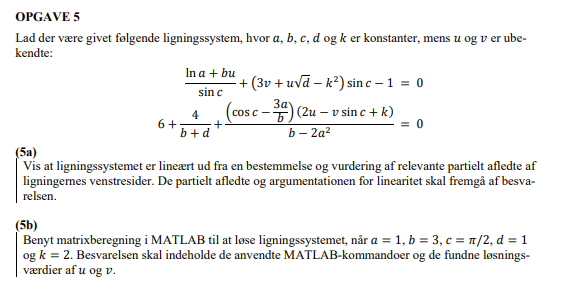

clear

syms u v a b c d k


l1 = (log(a) + b*u)/sin(c) + (3*v + u*sqrt(d) - k^2) *sin(c) - 1

l2 = 6 + 4/(b + d) + (cos(c) - (3*a/b)) * (2*u - v*sin(c) + k)/(b - 2*a^2)

vars = [u;v];

ls = [l1; l2];

J = jacobian(ls, vars)
c

clear all

syms u v

a = 1; b = 3; c = pi/2; d = 1; k = 2;

l1 = (log(a) + b*u)/sin(c) + (3*v + u*sqrt(d) - k^2) *sin(c) - 1;

l2 = 6 + 4/(b + d) + (cos(c) - (3*a/b)) * (2*u - v*sin(c) + k)/(b - 2*a^2);

vars = [u; v]

ls = [l1; l2]

[vars] = solve(ls, vars)


